# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Zeng\Newstruz\Instru\RawData'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 3 ;                                              % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = true;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false;                                                                  % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\User\Desktop\Zeng\Newstruz\Instru\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions

Deci.DT.Type = 'Manual';                                                                        % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {9};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {10};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[20 21 23 24] [27 28] [31 32] [51 52]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [14 30 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq
Deci.DT.Block.Start   = {11};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.End     = {12};                                                                       % Cell Array of Markers for Block Starts
Deci.DT.Block.Markers = [];                                                                     % Num Array for each type of Block (if empty, Blocks are deliminated chronologically as -1,-2,..etc)

## 2. PreProcessing Steps

Deci.PP.DownSample = [];                                                       % Downsample data
Deci.PP.More       = []   ;
Deci.PP.More.detrend = 'yes'

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 3
        Proceed: 1
           PCom: 0
             DT: [1×1 struct]
             PP: [1×1 struct]


Deci.PP.More.demean = 'yes'

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 3
        Proceed: 1
           PCom: 0
             DT: [1×1 struct]
             PP: [1×1 struct]


Deci.PP.More.hpfilter = 'yes';
Deci.PP.More.hpfreq = 1;

## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5];                                                                % Critical Time Period for trial rejection (Respective to first Lock and Last Lock)
Deci.Art.muscle     = [];                                                                       % if empty, use default muscle parameters
Deci.Art.eog        = [];                                                                       % if empty, use default eog parameters
Deci.Art.muscle.interactive = 'yes';
Deci.Art.eog.interactive = 'yes';
Deci.Art.postArtpreprocessing = [];


## 4. Analysis

#### General Set-Up

AllTrials;

#### Time-Frequency Analysis

Deci.Analysis.Freq.do            = true;
Deci_Wavelet;
Deci.Analysis.Freq.foi           = unique([linspace(4,8,12) linspace(8,13,12) linspace(13,30,12) linspace(30,60,12)]);
Deci.Analysis.Laplace = 0;
Deci.Analysis.Version = ['C:\Users\User\Desktop\Zeng\Newstruz\Instru\' 'ProcessedData'];

#### Cross-Frequency Coupling

Deci.Analysis.CFC.do = false;
Deci.Analysis.CFC.chanlow =  {'FCz'};
Deci.Analysis.CFC.chanhigh = {'CP3'};
Deci.Analysis.CFC.latencyhigh = [-.2 1]; %no implementation yet to check for edge artifacts so be careful
Deci.Analysis.CFC.latencylow = [-.2 1];
Deci.Analysis.CFC.freqhigh = 'theta';
Deci.Analysis.CFC.freqlow = 'beta';

Deci.Analysis.CFC.timebin = 6;
Deci.Analysis.CFC.methods = {'mi' 'plv'};  % can only currently handle '' or 'mi'(pac)

#### ERP

Deci.Analysis.ERP.do  = false;
Deci.Analysis.ERP.Toi = [-.5 1.5];

Extra

Deci.Analysis.Extra.QL.States = [20 21 23 24];
Deci.Analysis.Extra.QL.Actions = [31 32];
Deci.Analysis.Extra.QL.Reward  = [51 52];
Deci.Analysis.Extra.QL.Value  = {[20 10] [10 0] [0 -10] [-10 -20]};

Deci.Analysis.Extra.do = false;
Deci.Analysis.Extra.list = [true];
Deci.Analysis.Extra.Functions = {'QL'};
Deci.Analysis.Extra.Params = {{Deci.Analysis.Extra.QL}};

## 5. Plotting

Deci.Plot.Version = ['C:\Users\User\Desktop\Zeng\Newstruz\Instru\' 'ProcessedData'];
Deci.Plot.Lock = 'Stim Onset';
Deci.Plot.BslRef = 'Stim Onset';
Deci.Plot.GrandAverage = true;
Deci.Plot.FreqYScale = 'linear';


#### Conditions

Deci.Plot.IndexTitle = {'Opt CD Corr' 'Opt GH Corr' ...
                        'Opt AB Inc'  'Opt EF Inc'};

Deci.Plot.Math         = {'[x1 + x3]/2' '[x2 + x4]/2' '[x5 - x6]' '[x1 + x2]/2' '[x3 + x4]/2' '[x8 - x9]'};           % Condition Math done after Bsl, Condition Indexes are appended on.
Deci.Plot.Draw         = {[1 2 3 4] [5 6] [7] [8 9] [10]};                   % Cell array of Condition Index for each figure
Deci.Plot.Figures      = [true false false false false];                             % Which figure to plot currently
Deci.Plot.Title        = {'All Opt 10 trials' 'R v P' 'R - P' '+ v -' '+ - -'};          % Title for each figure
Deci.Plot.Subtitle     = {{'+R' '+P' '-R' '-P'} {'R' 'P'} {'R - P'} {'+' '-'} {'+ - -'}};     % Cell array of strings of subtitles for each Condition

#### Statistics

Deci.Plot.Stat.do = true;
Deci.Plot.Stat.Type = 'Anova/T-test';
Deci.Plot.Stat.alpha = .05;
Deci.Plot.Stat.correctm = 'no';
Deci.Plot.Stat.FPlots =  false;

#### Time-Frequency

Deci.Plot.Freq.Foi     = [4 8];                   % Frequency of Interest
Deci.Plot.Freq.Toi     = [];                   % Time of Interest
Deci.Plot.Freq.Channel = {'FCz'};                   % Channel of Interest
Deci.Plot.Freq.Type    = 'TotalPower';                   % Use 'TotalPower','ITPC' or 'EvokedPower' (Currently Unavailable)
%Deci.Plot.Freq.BslType     = 'relchange'
Deci.Plot.Freq.Bsl     = [-.5 -.2];                             % Baseline Correction Time
Deci.Plot.Freq.Topo    =false;
Deci.Plot.Freq.Square  =false;
Deci.Plot.Freq.Wire    =true;
Deci.Plot.Freq.Bar    =false;

**CFC**

%Currently Unavailable
Deci.Plot.CFC.Topo = true;
Deci.Plot.CFC.Square = true;
Deci.Plot.CFC.Hist = true;
Deci.Plot.CFC.Wire = true;
Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest

**ERP**

Deci.Plot.ERP.Toi = [0 .8];
Deci.Plot.ERP.Channel = {'FCz'};
Deci.Plot.ERP.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.ERP.Topo =true;
Deci.Plot.ERP.Wire =true;

#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Figure = [true false];
Deci.Plot.Behv.Acc.Total = {{[1:16] [1:16]} {[1 5 9 13] [2 6 10 14] [3 7 11 15] [4 8 12 16]}};
Deci.Plot.Behv.Acc.Subtotal = {{[1:8] [9:16]} {[1 5] [2 6] [3 7] [4 8]}};
Deci.Plot.Behv.Acc.Title = {'All Trials Percent' 'All Trials Percent'};
Deci.Plot.Behv.Acc.Subtitle = {{'Opt Percent' 'Wst Percent'} {'AB' 'CD' 'EF' 'GH'}};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =true;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = false;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'positional:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  false;


Deci.Plot.Behv.RT.Figure = [true false];
Deci.Plot.Behv.RT.Draw = {{[1:8] [9:16]}  {[1 5] [2 6] [3 7] [4 8] [9 13] [10 14] [11 15] [12 16]} {}};
Deci.Plot.Behv.RT.Title = {'All Trials RT' 'All Trials RT'};
Deci.Plot.Behv.RT.Subtitle = {{'Opt' 'Worst'} {'Opt AB' 'Opt CD' 'Opt EF' 'Opt GH' 'Wst AB' 'Wst CD' 'Wst EF' 'Wst GH'}};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = true;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

** Extra**

Deci.Plot.Extra.List = true;
Deci.Plot.Extra.Functions = {'QL'};
Deci.Plot.Extra.Params = {{}};

Options

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;
Deci.Run.Extra = false;

## ** 6. Run**

----------------------
Starting Artifactor
preprocessing
preprocessing trial 480 from 480

the call to "ft_preprocessing" took 37 seconds
the input is raw data with 62 channels and 480 trials
baseline correcting data 
scaling data with 1 over 135.344497
concatenating data................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................
concatenated data matrix size 62x4529221
starting decomposition using runica

Input data size [20,4529221] = 20 channels, 4529221 frames/nAfter PCA dimension reduction,
  finding 20 ICA components using logistic ICA.
Decomposing 11323 frames per I

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds


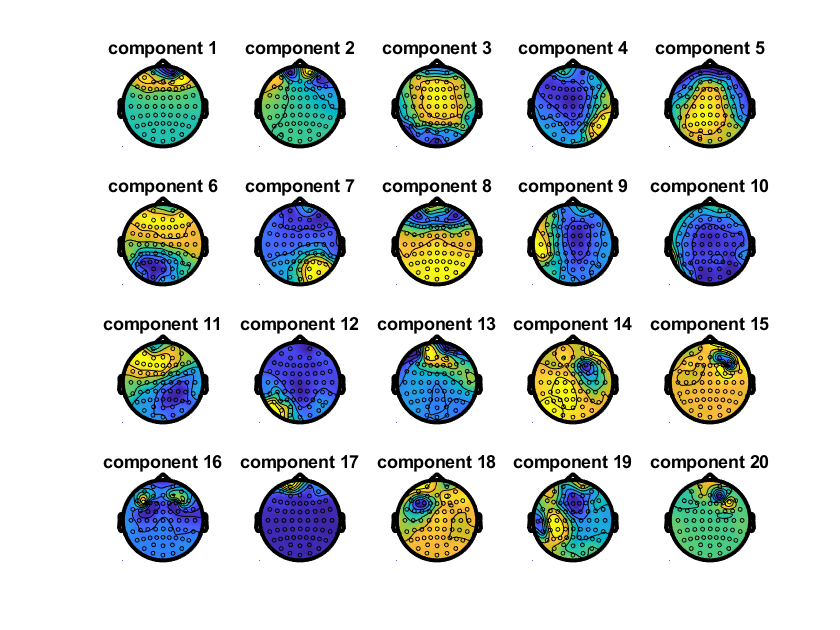

the call to "ft_topoplotIC" took 7 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the input is component data with 20 components and 62 original channels
the input is raw data with 20 channels and 480 trials
detected   0 visual artifacts


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.



removing 2 components
keeping 18 components
not applying the backprojection matrix to the sensor description
the call to "ft_rejectcomponent" took 1 seconds


showing trial   1, channel CP4
detected 8 artifacts
the call to "ft_artifact_zvalue" took 194 seconds


showing trial   1, channel RHEOG
detected 5 artifacts
the call to "ft_artifact_zvalue" took 44 seconds
detected   8 muscle artifacts
detected   5 eog artifacts
rejected    9 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
retained   10 trials with artifacts outside critical window
resulting 471 trials
the input is raw data with 62 channels and 480 trials


the call to "ft_redefinetrial" took 12 seconds
the call to "ft_rejectartifact" took 12 seconds
the input is raw data with 62 channels and 471 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 471 trials


showing a summary of the data for all channels and trials


computing metric [----|                                                    ]computing metric [---------/                                               ]computing metric [--------------                                           ]computing metric [------------------\                                      ]computing metric [----------------------|                                  ]computing metric [---------------------------/                             ]computing metric [--------------------------------                         ]computing metric [------------------------------------\                    ]computing metric [-----------------------------------------|               ]computing metric [---------------------------------------------/           ]computing metric [---------------------------------------------------      ]computing metric [-------------------------------------------------------\ ]computing metric [--------------------------------------------------------|]


463 trials marked as GOOD, 8 trials marked as BAD
4 channels marked as GOOD, 58 channels marked as BAD
no channels were removed from the data
the following trials were removed: 109, 137, 275, 342, 354, 374, 404, 447
the call to "ft_rejectvisual" took 119 seconds
the input is raw data with 62 channels and 463 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 463 trials


showing a summary of the data for all channels and trials


computing metric [----|                                                    ]computing metric [--------/                                                ]computing metric [-------------                                            ]computing metric [----------------\                                        ]computing metric [---------------------|                                   ]computing metric [-------------------------/                               ]computing metric [-------------------------------                          ]computing metric [----------------------------------\                      ]computing metric [---------------------------------------|                 ]computing metric [--------------------------------------------/            ]computing metric [-------------------------------------------------        ]computing metric [-----------------------------------------------------\   ]computing metric [--------------------------------------------------------|]


452 trials marked as GOOD, 11 trials marked as BAD
62 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 145, 147, 148, 157, 217, 312, 317, 329, 365, 391, 396
the call to "ft_rejectvisual" took 36 seconds


the input is raw data with 62 channels and 86 trials
resampling data
resampling data in trial 86 from 86

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 3 seconds
the input is raw data with 62 channels and 86 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 86 trials


processing trials
trial 86, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 101 seconds
s:1 c:1 Lock1 time: 24.52
the input is raw data with 62 channels and 86 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 86 trials


processing trials
trial 86, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 98 seconds
s:1 c:1 Lock2 time: 24.328
the input is raw data with 62 channels and 86 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 86 trials


processing trials
trial 86, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 101 seconds
s:1 c:1 Lock3 time: 24.322
s:1 c:1 Cond time: 378.884
the input is raw data with 62 channels and 80 trials
resampling data
resampling data in trial 80 from 80

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 3 seconds
the input is raw data with 62 channels and 80 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 80 trials


processing trials
trial 80, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 93 seconds
s:1 c:2 Lock1 time: 27.456
the input is raw data with 62 channels and 80 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 80 trials


processing trials
trial 80, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 87 seconds
s:1 c:2 Lock2 time: 23.769
the input is raw data with 62 channels and 80 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 80 trials


processing trials
trial 80, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 88 seconds
s:1 c:2 Lock3 time: 23.857
s:1 c:2 Cond time: 349.225
the input is raw data with 62 channels and 73 trials
resampling data
resampling data in trial 73 from 73

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 2 seconds
the input is raw data with 62 channels and 73 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 73 trials


processing trials
trial 73, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 79 seconds
s:1 c:3 Lock1 time: 22.554
the input is raw data with 62 channels and 73 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 73 trials


processing trials
trial 73, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 80 seconds
s:1 c:3 Lock2 time: 22.644
the input is raw data with 62 channels and 73 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 73 trials


processing trials
trial 73, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 80 seconds
s:1 c:3 Lock3 time: 22.534
s:1 c:3 Cond time: 311.462
the input is raw data with 62 channels and 24 trials
resampling data
resampling data in trial 24 from 24

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 1 seconds
the input is raw data with 62 channels and 24 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 24 trials


processing trials
trial 24, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 26 seconds
s:1 c:4 Lock1 time: 16.051
the input is raw data with 62 channels and 24 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 24 trials


processing trials
trial 24, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 26 seconds
s:1 c:4 Lock2 time: 16.153
the input is raw data with 62 channels and 24 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 24 trials


processing trials
trial 24, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 26 seconds
s:1 c:4 Lock3 time: 16.148
s:1 c:4 Cond time: 128.425
the input is raw data with 62 channels and 13 trials
resampling data
resampling data in trial 13 from 13

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 1 seconds
the input is raw data with 62 channels and 13 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 13 trials


processing trials
trial 13, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 14 seconds
s:1 c:5 Lock1 time: 14.038
the input is raw data with 62 channels and 13 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 13 trials


processing trials
trial 13, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 14 seconds
s:1 c:5 Lock2 time: 14.164
the input is raw data with 62 channels and 13 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 13 trials


processing trials
trial 13, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 14 seconds
s:1 c:5 Lock3 time: 14.076
s:1 c:5 Cond time: 86.76
the input is raw data with 62 channels and 16 trials
resampling data
resampling data in trial 16 from 16

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 1 seconds
the input is raw data with 62 channels and 16 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 16 trials


processing trials
trial 16, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 18 seconds
s:1 c:6 Lock1 time: 14.693
the input is raw data with 62 channels and 16 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 16 trials


processing trials
trial 16, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 18 seconds
s:1 c:6 Lock2 time: 14.847
the input is raw data with 62 channels and 16 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 16 trials


processing trials
trial 16, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 17 seconds
s:1 c:6 Lock3 time: 14.258
s:1 c:6 Cond time: 97.98
the input is raw data with 62 channels and 15 trials
resampling data
resampling data in trial 15 from 15

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 1 seconds
the input is raw data with 62 channels and 15 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 15 trials


processing trials
trial 15, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 11 seconds
s:1 c:7 Lock1 time: 14.496
the input is raw data with 62 channels and 15 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 15 trials


processing trials
trial 15, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 16 seconds
s:1 c:7 Lock2 time: 14.648
the input is raw data with 62 channels and 15 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 15 trials


processing trials
trial 15, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 17 seconds
s:1 c:7 Lock3 time: 14.608
s:1 c:7 Cond time: 89.88
the input is raw data with 62 channels and 101 trials
resampling data
resampling data in trial 101 from 101

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 3 seconds
the input is raw data with 62 channels and 101 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 101 trials


processing trials
trial 101, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 110 seconds
s:1 c:8 Lock1 time: 27.02
the input is raw data with 62 channels and 101 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 101 trials


processing trials
trial 101, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 109 seconds
s:1 c:8 Lock2 time: 27.178
the input is raw data with 62 channels and 101 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 101 trials


processing trials
trial 101, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 113 seconds
s:1 c:8 Lock3 time: 27.717
s:1 c:8 Cond time: 419.889
the input is raw data with 62 channels and 6 trials
resampling data
resampling data in trial 6 from 6

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 0 seconds
the input is raw data with 62 channels and 6 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 6 trials


processing trials
trial 6, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 7 seconds
s:1 c:9 Lock1 time: 13.27
the input is raw data with 62 channels and 6 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 6 trials


processing trials
trial 6, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 7 seconds
s:1 c:9 Lock2 time: 13.274
the input is raw data with 62 channels and 6 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 6 trials


processing trials
trial 6, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 7 seconds
s:1 c:9 Lock3 time: 13.571
s:1 c:9 Cond time: 62.571
the input is raw data with 62 channels and 3 trials
resampling data
resampling data in trial 3 from 3

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 0 seconds
the input is raw data with 62 channels and 3 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 3 trials


processing trials
trial 3, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 3 seconds
s:1 c:10 Lock1 time: 12.295
the input is raw data with 62 channels and 3 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 3 trials


processing trials
trial 3, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 3 seconds
s:1 c:10 Lock2 time: 12.563
the input is raw data with 62 channels and 3 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 3 trials


processing trials
trial 3, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 3 seconds
s:1 c:10 Lock3 time: 12.49
s:1 c:10 Cond time: 48.626
the input is raw data with 62 channels and 3 trials
resampling data
resampling data in trial 3 from 3

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 0 seconds
the input is raw data with 62 channels and 3 trials


removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 3 trials


processing trials
trial 3, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 3 seconds
s:1 c:11 Lock1 time: 12.645
the input is raw data with 62 channels and 3 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 3 trials


processing trials
trial 3, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 3 seconds
s:1 c:11 Lock2 time: 12.489
the input is raw data with 62 channels and 3 trials


removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 3 trials


processing trials
trial 3, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 3 seconds
s:1 c:11 Lock3 time: 12.787
s:1 c:11 Cond time: 49.149
the input is raw data with 62 channels and 3 trials
resampling data
resampling data in trial 3 from 3

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 0 seconds
the input is raw data with 62 channels and 3 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 3 trials


processing trials
trial 3, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 3 seconds
s:1 c:12 Lock1 time: 12.48
the input is raw data with 62 channels and 3 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 3 trials


processing trials
trial 3, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 3 seconds
s:1 c:12 Lock2 time: 12.755
the input is raw data with 62 channels and 3 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 3 trials


processing trials
trial 3, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 3 seconds
s:1 c:12 Lock3 time: 12.496
s:1 c:12 Cond time: 48.883
the input is raw data with 62 channels and 30 trials
resampling data
resampling data in trial 30 from 30

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 1 seconds
the input is raw data with 62 channels and 30 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 30 trials


processing trials
trial 30, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 33 seconds
s:1 c:13 Lock1 time: 17.071
the input is raw data with 62 channels and 30 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 30 trials


processing trials
trial 30, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 33 seconds
s:1 c:13 Lock2 time: 16.957
the input is raw data with 62 channels and 30 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 30 trials


processing trials
trial 30, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 33 seconds
s:1 c:13 Lock3 time: 16.964
s:1 c:13 Cond time: 153.701
the input is raw data with 62 channels and 12 trials
resampling data
resampling data in trial 12 from 12

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 0 seconds
the input is raw data with 62 channels and 12 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 12 trials


processing trials
trial 12, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 14 seconds
s:1 c:14 Lock1 time: 14.138
the input is raw data with 62 channels and 12 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 12 trials


processing trials
trial 12, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 13 seconds
s:1 c:14 Lock2 time: 14.008
the input is raw data with 62 channels and 12 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 12 trials


processing trials
trial 12, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 13 seconds
s:1 c:14 Lock3 time: 14.081
s:1 c:14 Cond time: 84.252
the input is raw data with 62 channels and 20 trials
resampling data
resampling data in trial 20 from 20

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 1 seconds
the input is raw data with 62 channels and 20 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 20 trials


processing trials
trial 20, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 22 seconds
s:1 c:15 Lock1 time: 15.506
the input is raw data with 62 channels and 20 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 20 trials


processing trials
trial 20, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 22 seconds
s:1 c:15 Lock2 time: 15.589
the input is raw data with 62 channels and 20 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 62 channels and 20 trials


processing trials
trial 20, frequency 45 (59.98 Hz)

the call to "ft_freqanalysis" took 22 seconds
s:1 c:15 Lock3 time: 15.257
s:1 c:15 Cond time: 115.321
Analyzed for Instru_EEG_079 Time: 2438.998
Full Analysis Time:2439.001
Channel FCz of 1
Elapsed time is 0.017144 seconds.
Channel FCz of 1
Elapsed time is 0.075407 seconds.
Channel FCz of 1
Elapsed time is 0.137460 seconds.
Channel FCz of 1
Elapsed time is 0.193932 seconds.
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds


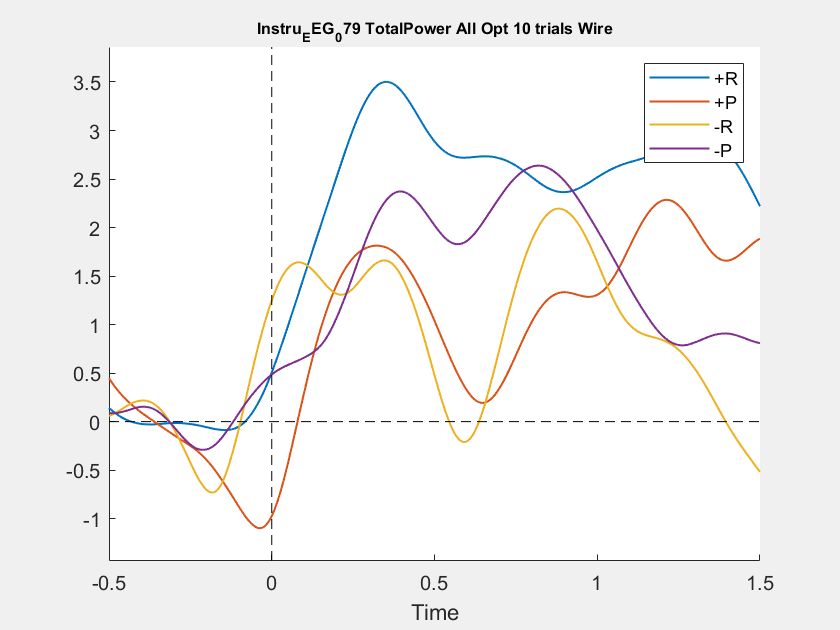

the call to "ft_singleplotER" took 0 seconds


Deci_Backend(Deci);